# Create and Customize Heatmaps

Heatmap charts display matrices as colors selected from a color map.

### Read Bicycle Data

We will use "`cambridgeData.mat" `to demonstrate how to create and customize heat maps. The MAT-file contains a table with various ride data from Boston's bike sharing program. 

load cambridgeData.mat cambridge;

### Basic Heatmap

Create a heatmap of Day`OfWeek` vs. `AgeGroup`, with color representing the number of rides. Young riders are clearly the most frequent users of this bike sharing program.

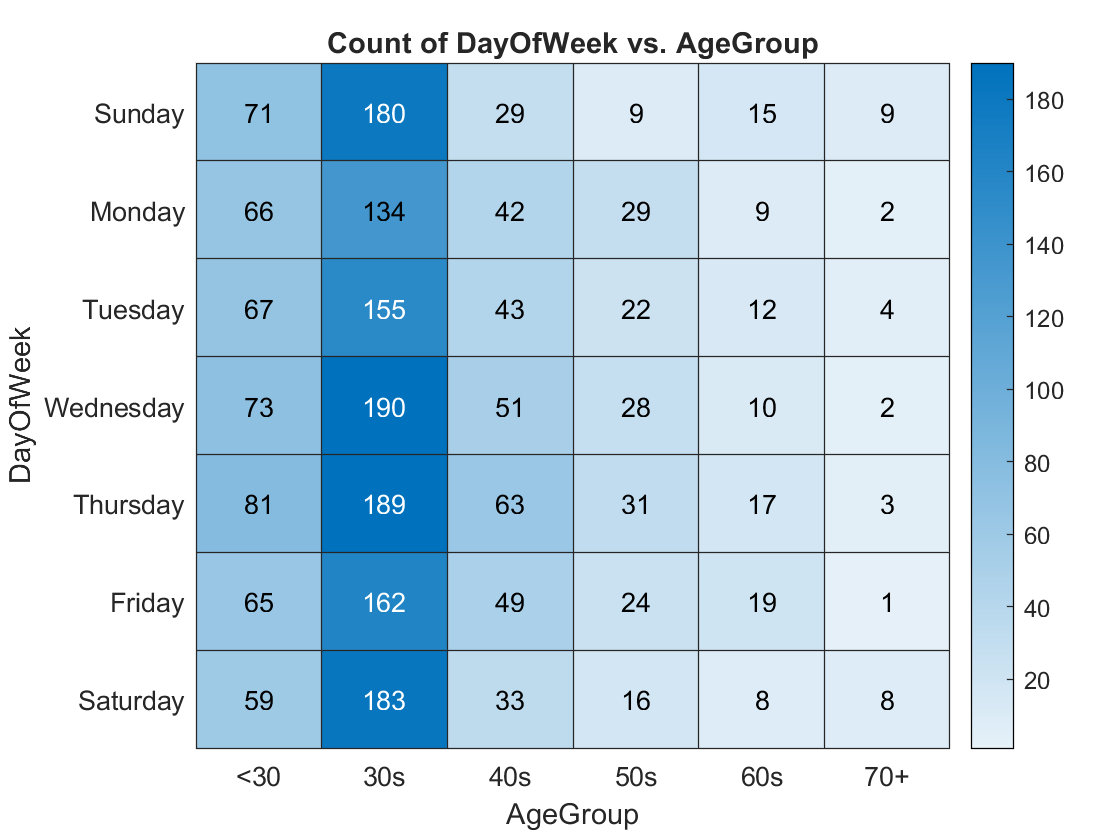

heatmap(cambridge,"AgeGroup","DayOfWeek");

## Customization

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu.

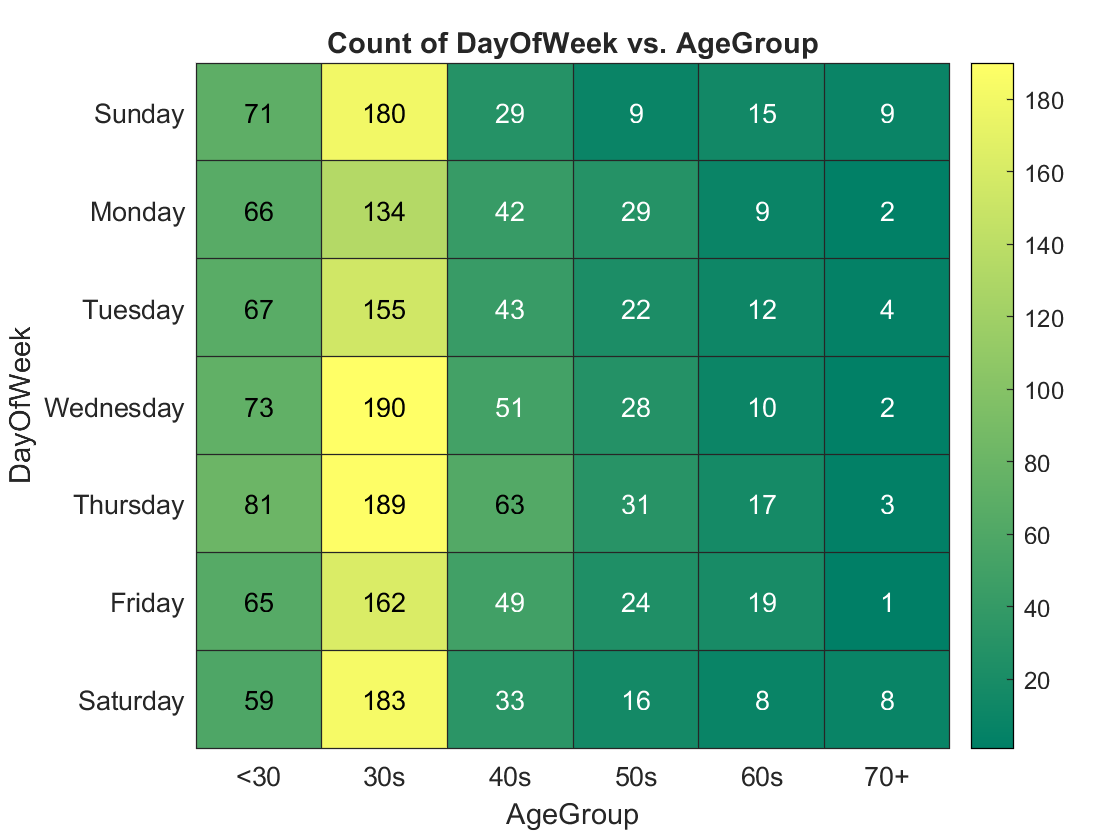

h = heatmap(cambridge,"AgeGroup","DayOfWeek");
colormap("summer"); % Specify colormap

### Specify Table Variable for Heatmap Colors

Instead of the count of bicycles, color each cell using the average or median of another variable by setting the *ColorVariable* and *ColorMethod* options. For example, color each cell with the mean duration of rides. This highlights that the longest rides on average are by older cyclists on a Sunday.

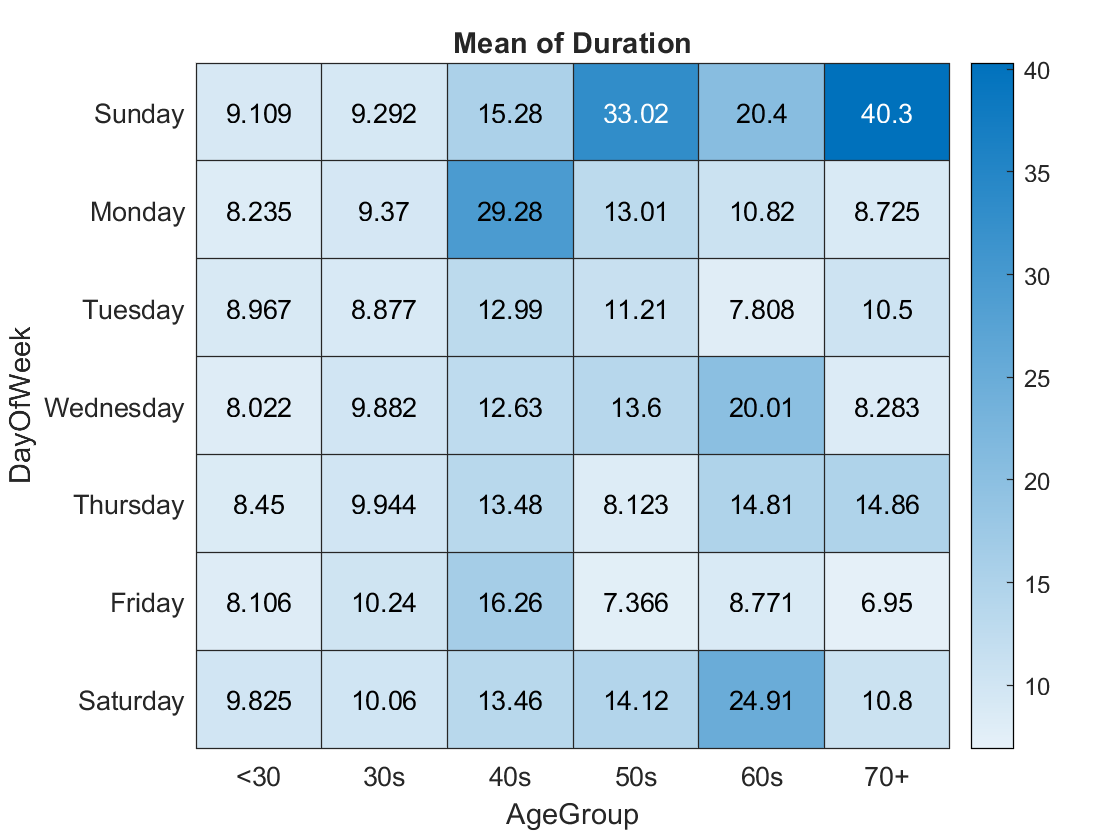

colorMethod = "mean";

figure
h1 = heatmap(cambridge,"AgeGroup","DayOfWeek",...
    "ColorVariable","Duration",...  % Specify the variable used to color cells
    "ColorMethod",colorMethod);     % Specify the method used to color cells

### Modify X-axis Labels

The x-axis labels can be customized by modifying the *XDisplayLabels* property as a Name, Value pair argument to the `heatmap` function call. Instead of labels saying 30s, 40s, etc, specify the precise age range in each label.

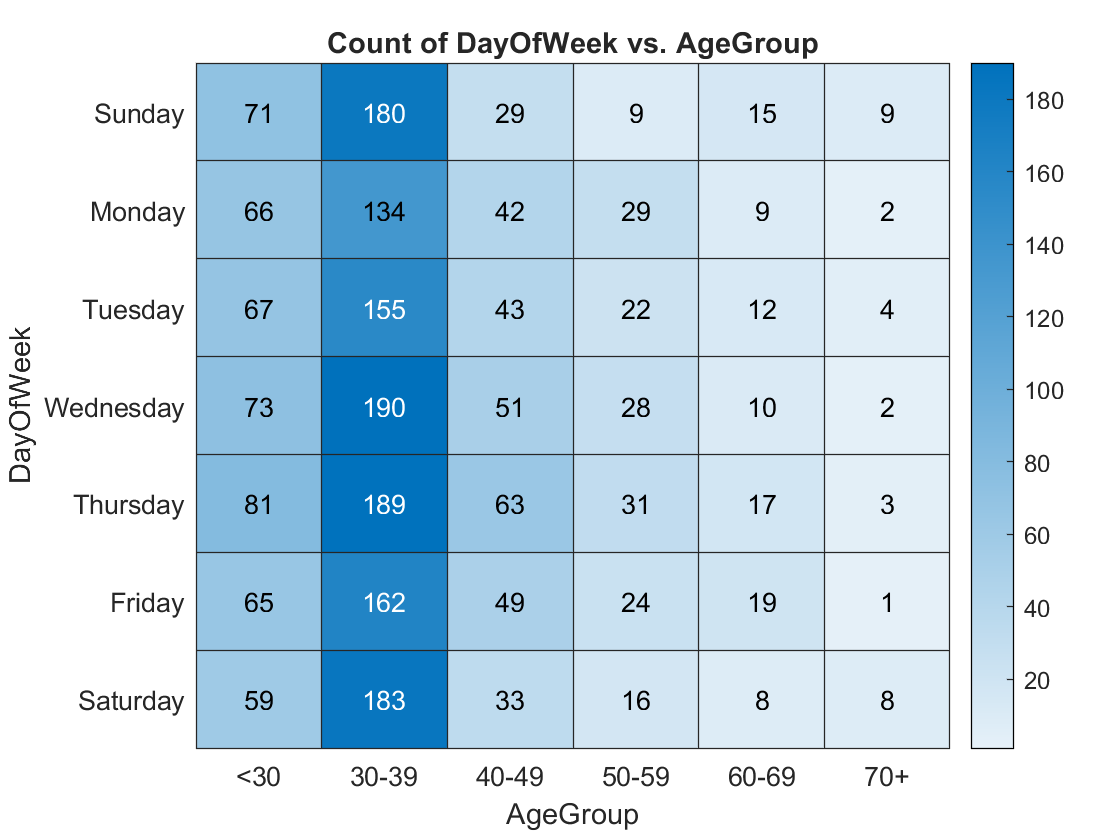

h2 = heatmap(cambridge,"AgeGroup","DayOfWeek",...
    "XDisplayLabels",["<30","30-39","40-49","50-59","60-69","70+"]);  % Specify custom labels

## **Additional Information**

### **Get All HeatmapChart Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a HeatmapChart, uncomment the following code. View or modify these properties using dot notation.

% get(h)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[heatmap](https://www.mathworks.com/help/matlab/ref/heatmap.html)

Copyright (c) 2021, The MathWorks, Inc.